data = data5(end-499:end,:);
% Indicador R datos originales
C = cov(data);
CI = inv(C);
d1 = diag(C);
d2 = diag(CI);
R = 1 - 1./(d1.*d2)

R =     0.7949
    0.7234
    0.6052
    0.5482
    0.8139


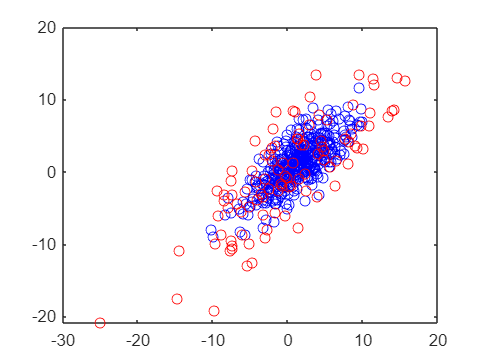

D = mahal(data,data);
plot(data(:,1),data(:,2), 'ob')
hold on;
pc = prctile(D,80);
I = find(D>pc);
plot(data(I,1),data(I,2),'or')
hold off;

datafiltrado = data;
datafiltrado(I,:) = [];
%Indicador R datos recortados
C = cov(datafiltrado);
CI = inv(C);
d1 = diag(C);
d2 = diag(CI);
Rfiltrado = 1 - 1./(d1.*d2)

Rfiltrado =     0.7750
    0.7117
    0.6772
    0.6012
    0.8055


## Punto 2.b Correlacion de Kendall

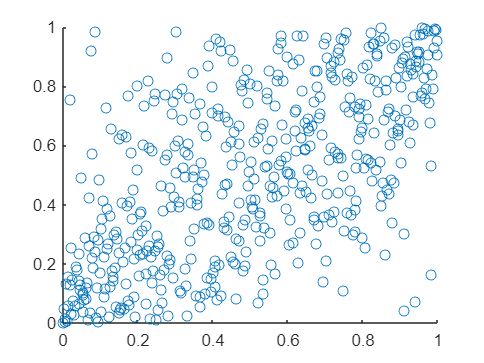

kendall = corr(data, 'type', 'Kendall');

minimo = min(kendall,[],"all");
[a, b] = find(kendall == minimo,1);

x = data(:,a);
y = data(:,b);
scatter(empiric(x),empiric(y))

## Punto 2.c Proyeccion maxima y minima variabilidad

C = cov([x,y]);
[vector, valor] = eig(C)

function [emp] = empiric(col)

vector =     0.6796   -0.7336
   -0.7336   -0.6796


valor =     7.4669         0
         0   33.3259


    n = length(col);
    emp = [];
    for i = 1:length(col)
        ratio = (length(col(col<=col(i))))/n;
        emp = [emp, ratio];
    end

end